# 1 创建环境

% 利用MATLAB中预定义好的环境直接创建
env = rlPredefinedEnv('CartPole-Discrete');

% 查看环境的状态和动作规范
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

% 固定随机种子确保实验的可重复性
rng(0)

# 2 创建智能体

% 神经网络创建
layers =[
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(200)
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(length(actInfo.Elements))];

% 将神经网络转化成dlnetwork类型
net = dlnetwork(layers);

% 将神经网络拟合critic
critic = rlVectorQValueFunction(net,obsInfo,actInfo);

% 设置critic的优化选项
crticOpts = rlOptimizerOptions(LearnRate=1e-3,GradientThreshold=1);

% 设置DQN超参数
agentoption = rlDQNAgentOptions( ...
    SampleTime=0.1, ...
    CriticOptimizerOptions=crticOpts, ...
    MiniBatchSize=256, ...
    UseDoubleDQN=false);

% 正式创建DQN智能体
agent = rlDQNAgent(critic,agentoption);

# 3 训练算法并保存

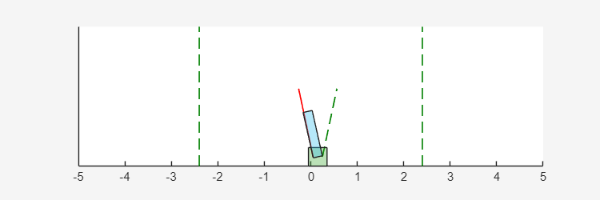

% 设置训练选项
trainOpts = rlTrainingOptions( ...
    "MaxEpisodes",200, ...
    "MaxStepsPerEpisode",400, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",400, ...
    "SaveAgentCriteria","AverageReward", ...
    "SaveAgentValue",100);

% 可视化u推杆系统
plot(env)

% 正式开始训练智能体
trainingStats = train(agent,env,trainOpts);

# 4 使用训练好的智能体与环境交互

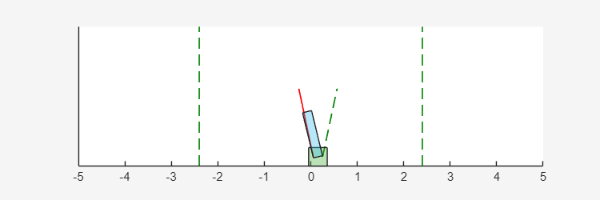

plot(env)

% 设置仿真选项
simoptions = rlSimulationOptions(MaxSteps=500);

% 训练好的智能体与环境进行交互
sim(env,agent,simoptions)